# COVID19 Mask Detection

## Test Trained model with sample still image

#### Read a test image into the workspace.

load COVID19_Mask_yolo.mat

#### Import still image and test the trained model

I = imread("sample.jpg");
resz = [224 224];
Ir = imresize(I, resz);

#### You can rather select to run 'yolov2_detect_mex' file for inference acceleration

[bbox,score,label] = detect(detector, Ir, 'threshold', 0.7);
% [bbox,score, label] = yolov2_detect_mex(Ir, 0.7)

#### Display the results.

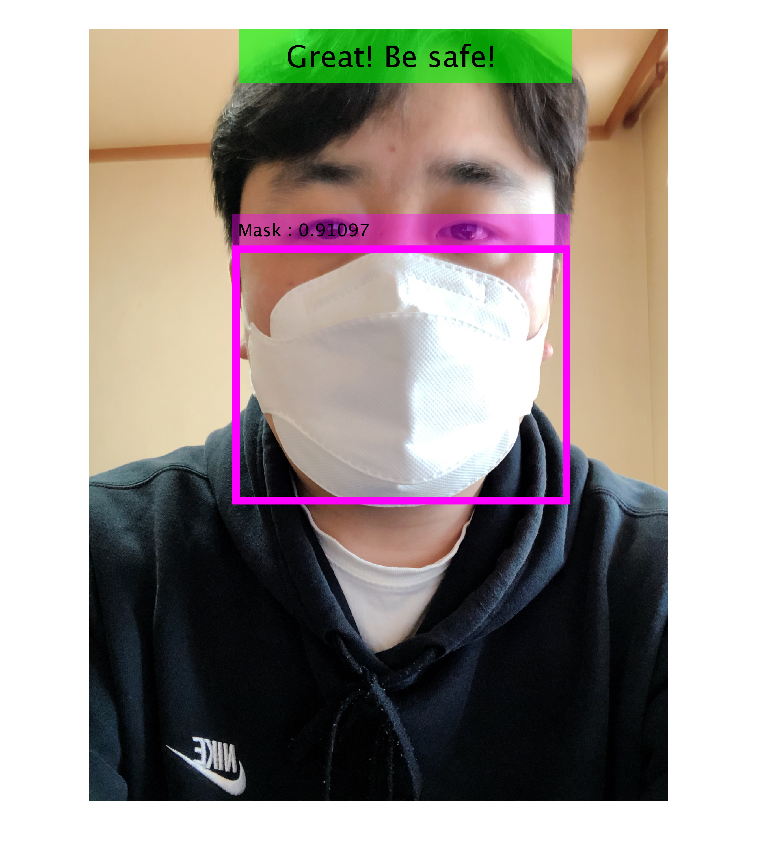

if(~isempty(bbox))
    bboxf = bboxre(bbox, size(I), resz);
    detectedImg = insertObjectAnnotation(I, 'rectangle', bboxf, [string(label)+ " : "+string(score)], 'Color', 'magenta', ...
            'Fontsize', 70, 'linewidth', 30, 'textboxopacity', 0.4);
end
detectedImg = insertText(detectedImg, [600, 1],  "    Great! Be safe!       ", 'FontSize', 120, 'BoxColor', 'g');

figure
clf
imshow(detectedImg)

function bbox = bboxre(bbox, sz, targetSize)
bbox(:,1) = bbox(:,1)*sz(2)/targetSize(2);
bbox(:,2) = bbox(:,2)*sz(1)/targetSize(1);
bbox(:,3) = bbox(:,3)*sz(2)/targetSize(2);
bbox(:,4) = bbox(:,4)*sz(1)/targetSize(1);
end

*Copyright 2020 The MathWorks, Inc.*